# Detect and Match Features 

This example shows how you can detect, describe and match features between two images. 

We highly recommend you to complete the [Image Processing Onramp](http://bit.ly/2OOtJiB).

Copyright 2021 The MathWorks, Inc.

close all; clear; clc;
rng(250);

## Read a Video and Capture Frame

Read an image frame from the video using Video Reader object. 

targetVid = "moveCamera.mp4";
vidObj = VideoReader(targetVid);

Set a target frame：

frameIndex =  250;

Read an image frame and display it

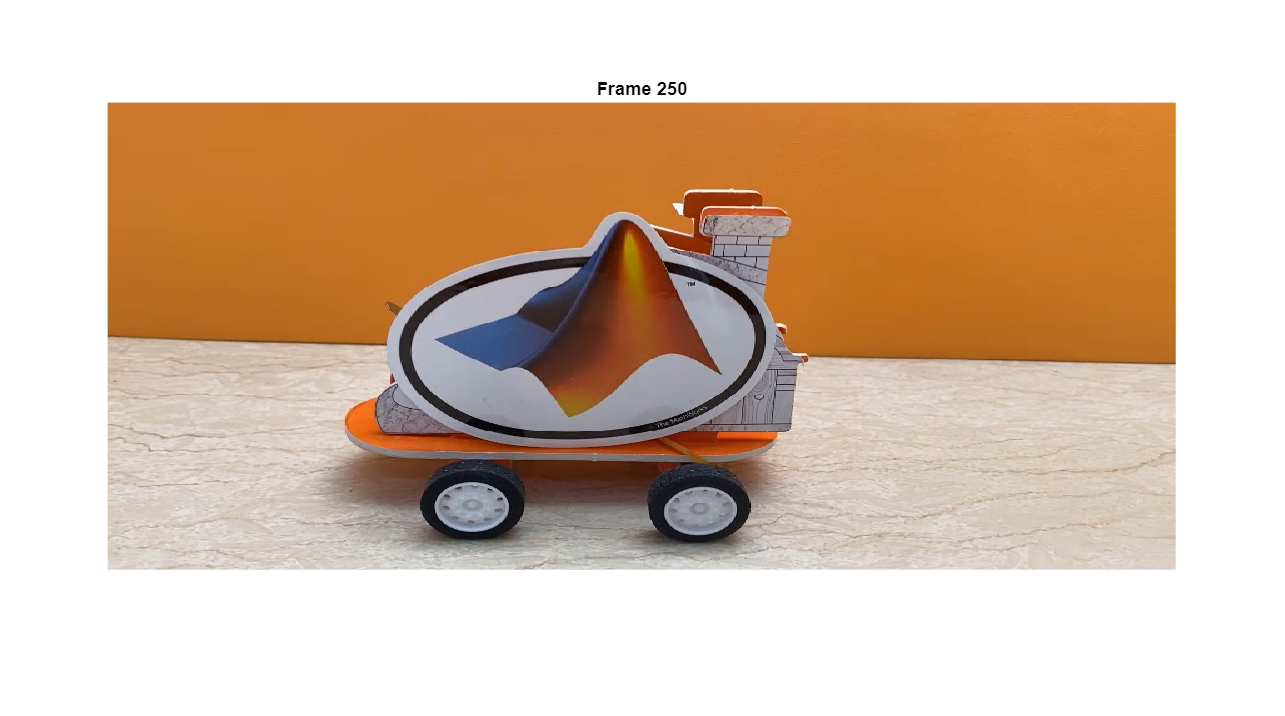

frameImg = read(vidObj, frameIndex);

figure
imshow(frameImg)
title(['Frame ' num2str(frameIndex)])

Change the color space to intensity (grayscale). 

frameImgGray = im2gray(frameImg);

## Detect and Extract Features in Frame Image

[Local features](https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html) refer to a pattern or distinct structure found in an image, such as a point, edge, or small image patch. They are usually associated with an image patch that differs from its immediate surroundings by texture, color, or intensity. What the feature actually represents does not matter, just that it is distinct from its surroundings. Good local features exhibit the following properties:

- **Repeatable detections**:When given two images of the same scene, most features that the detector finds in both images are the same. The features are robust to changes in viewing conditions and noise.

- **Distinctive**:The neighborhood around the feature center varies enough to allow for a reliable comparison between the features.

- **Localizable**:The feature has a unique location assigned to it. Changes in viewing conditions do not affect its location.

### Detect and Extract Scale-Dependent Features

Detect scale-dependent features.

framePtsD = detectHarrisFeatures(frameImgGray);

[Extract feature vectors](https://www.mathworks.com/help/vision/ref/extractfeatures.html), also known as descriptors, and their corresponding locations, from a binary or intensity image. The function derives the descriptors from pixels surrounding an interest point. The pixels represent and match features specified by a single-point location. Specify descriptor extraction method, specified as a comma-separated pair consisting of '`Method`' and '`FREAK`', '`SURF`', '`ORB`', `Block`', or '`Auto`' (default) depending on the data you are working on. 

[frameDescriptorsD,validFramePtsD]  = extractFeatures(frameImgGray, framePtsD); %'Auto'(default): FREAK Descriptor

Display the scale-dependent features.

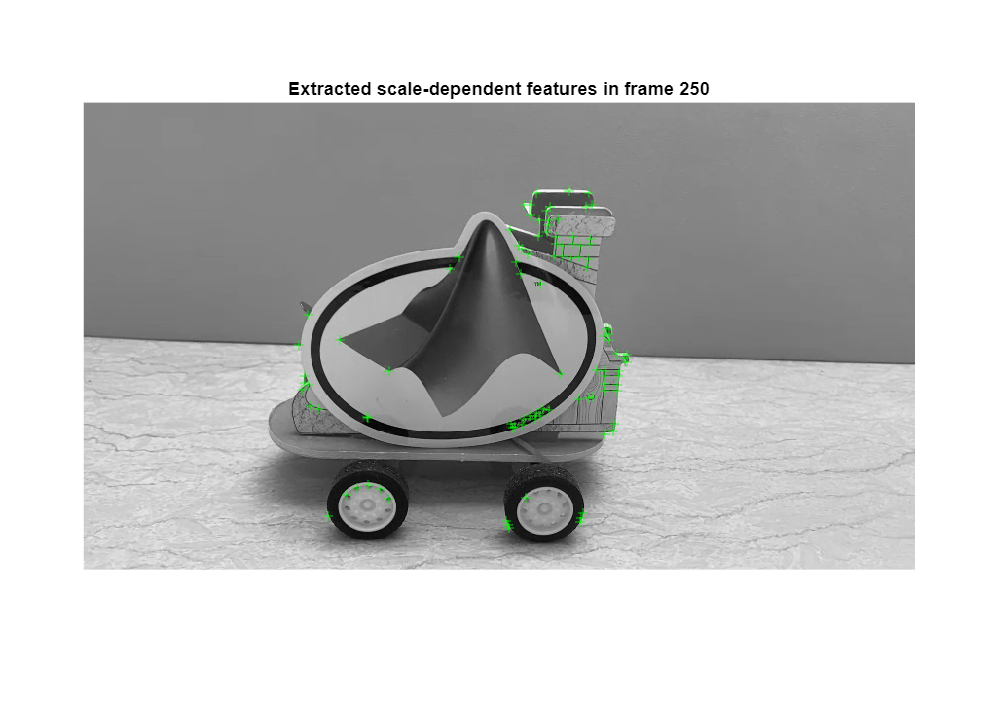

figure
imshow(frameImgGray);
hold on;
plot(selectStrongest(validFramePtsD,100));
title(['Extracted scale-dependent features in frame ' num2str(frameIndex)])

### Detect and Extract Scale-Independent Features

Detect scale-independent features.

framePtsI = detectSURFFeatures(frameImgGray);

Extract the discriptors of scale-independent features.

[frameDescriptorsI,validFramePtsI]  = extractFeatures(frameImgGray, framePtsI); %'Auto'(default): SURF

 Display scale-independent features.

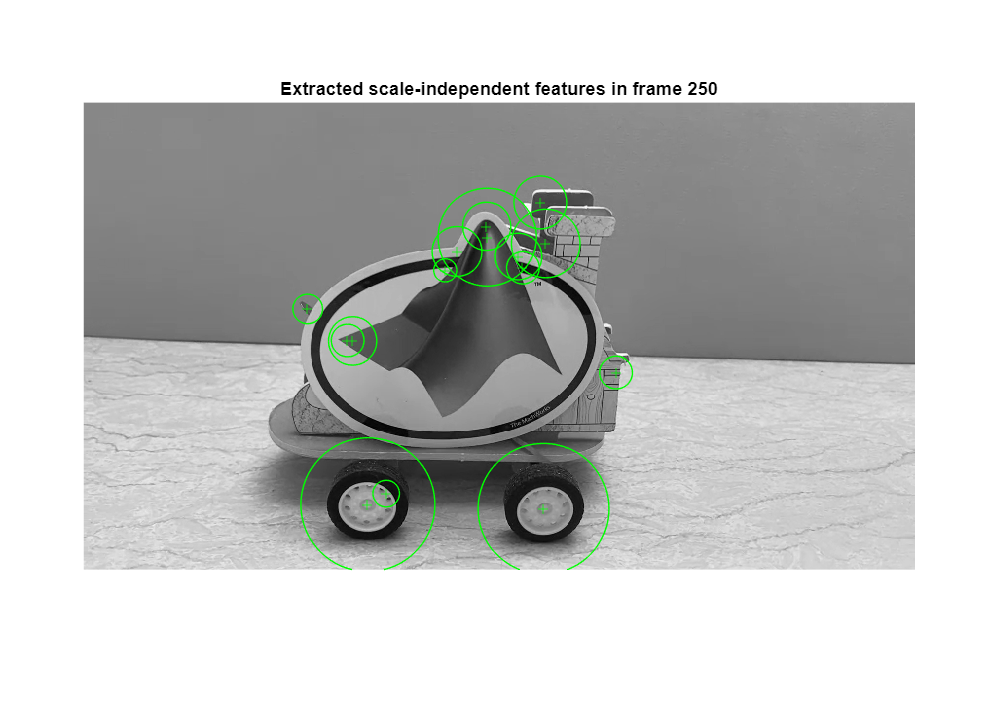

figure
imshow(frameImgGray);
hold on;
plot(selectStrongest(validFramePtsI,15));
title(['Extracted scale-independent features in frame ' num2str(frameIndex)])

Check the section on[ Choose a Feature Detector and Descriptor](https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html) on when to choose what Feature Detector and Descriptor

## Detect and Extract features in Reference Image 

Read a reference image。

refImg = imread("MWLogo.jpg");

Resize it to save computational cost, and display it.

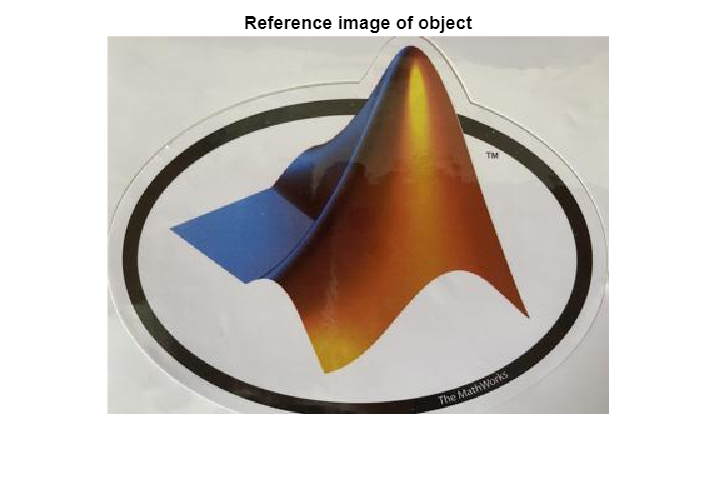

scalingFactor = 1;
refImg = imresize(refImg,scalingFactor);

figure
imshow(refImg)
title('Reference image of object')

Change color space to Gray

refImgGray = im2gray(refImg);

### Detect and Extract Scale-Dependent Features

Detect scale-dependent features

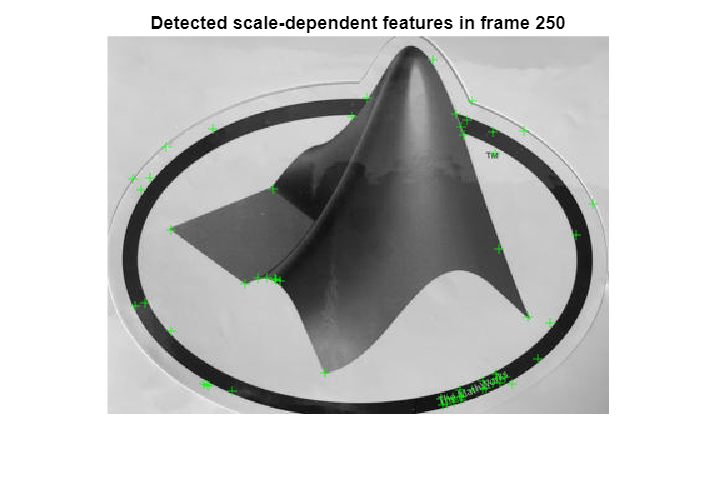

refPtsD = detectHarrisFeatures(refImgGray);

figure
imshow(refImgGray);
hold on;
plot(refPtsD);
title(['Detected scale-dependent features in frame ' num2str(frameIndex)])

Extract scale-dependent features

[refDescriptorsD,validRefPtsD]  = extractFeatures(refImgGray, refPtsD);

### Detect and Extract Scale-independent Features

Detect scale-independent features 

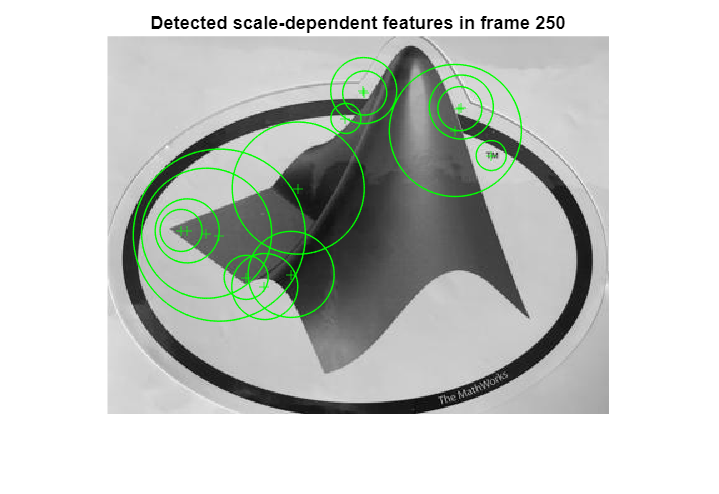

refPtsI = detectSURFFeatures(refImgGray);

figure
imshow(refImgGray);
hold on;
plot(selectStrongest(refPtsI,15));
title(['Detected scale-dependent features in frame ' num2str(frameIndex)])

Extract scale-independent features 

[refDescriptorsI,validRefPtsI]  = extractFeatures(refImgGray, refPtsI); %auto: SURF

## Match Features

### Match Scale-Dependent Features

featurePairsD = matchFeatures(frameDescriptorsD, refDescriptorsD);

Get putatively matched feature points

matchedFramePtsD = validFramePtsD(featurePairsD(:, 1), :);
matchedRefPtsD = validRefPtsD(featurePairsD(:, 2), :);

Display the putatively matching point pairs (including outliers)

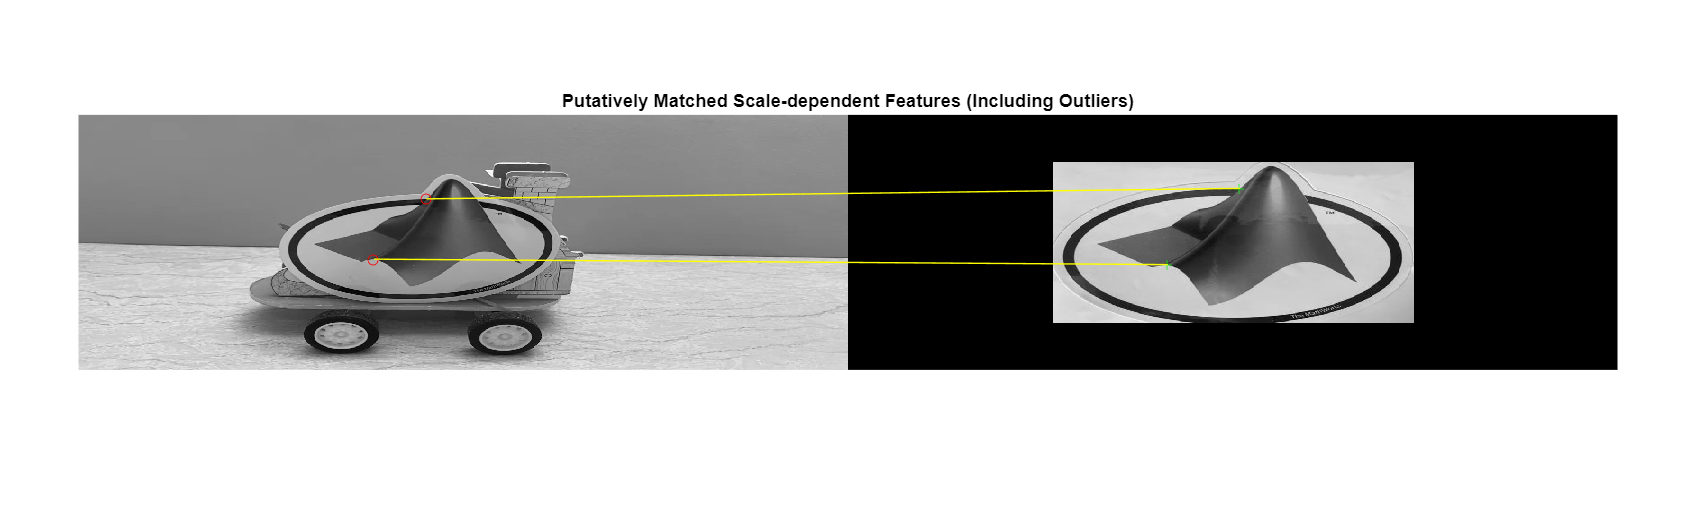

figure;
showMatchedFeatures(frameImgGray, refImgGray, matchedFramePtsD, ...
    matchedRefPtsD,'montage');
title('Putatively Matched Scale-dependent Features (Including Outliers)');

### Match Scale-Independent Features 

featurePairsI = matchFeatures(frameDescriptorsI, refDescriptorsI);

Get putatively matched feature points

matchedFramePtsI = validFramePtsI(featurePairsI(:, 1), :);
matchedRefPtsI = validRefPtsI(featurePairsI(:, 2), :);

Display the putatively matching point pairs (including outliers)

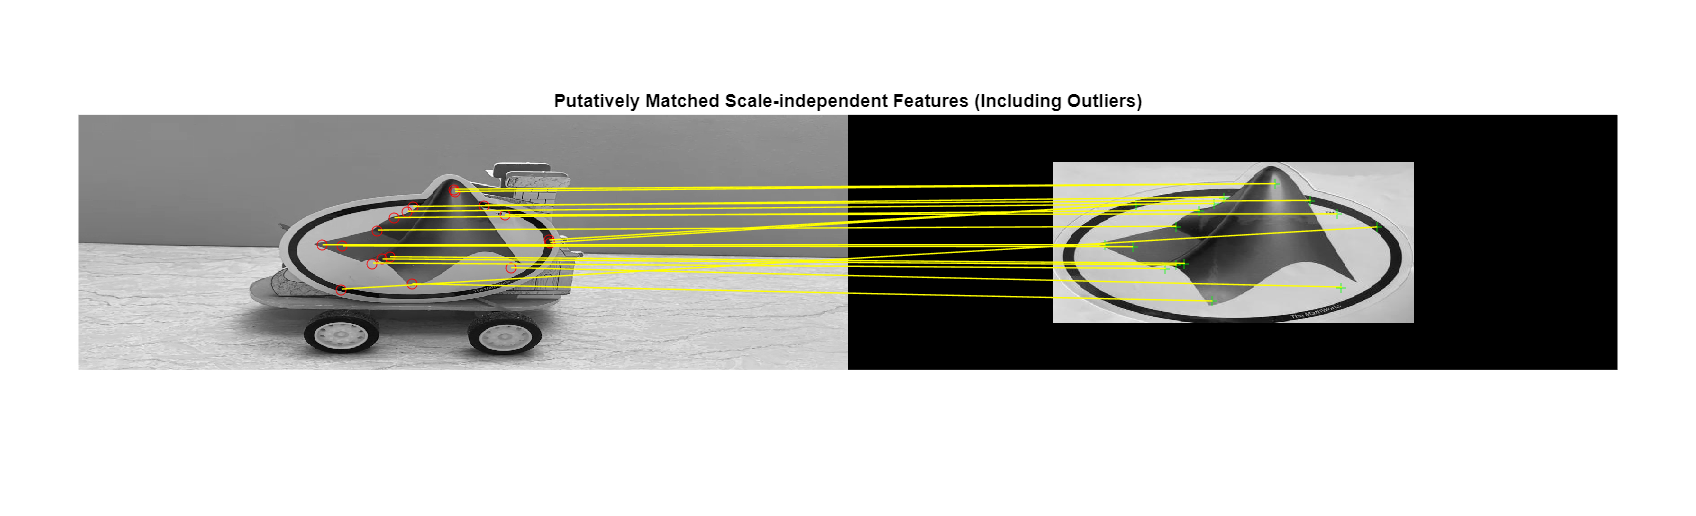

figure;
showMatchedFeatures(frameImgGray, refImgGray, matchedFramePtsI, ...
    matchedRefPtsI,'montage');
title('Putatively Matched Scale-independent Features (Including Outliers)');

## Eliminate Outliers

### Estimate Geometric Transformation in Scale-Dependent Case

[tformD, inlierIdxD, statusD] = ...
    estimateGeometricTransform2D(matchedRefPtsD, matchedFramePtsD,'similarity'); % status = 0: No error; 1: not enough input points; 2: not enough inliers have been found

If there are enough inliers, display the matching point pairs.

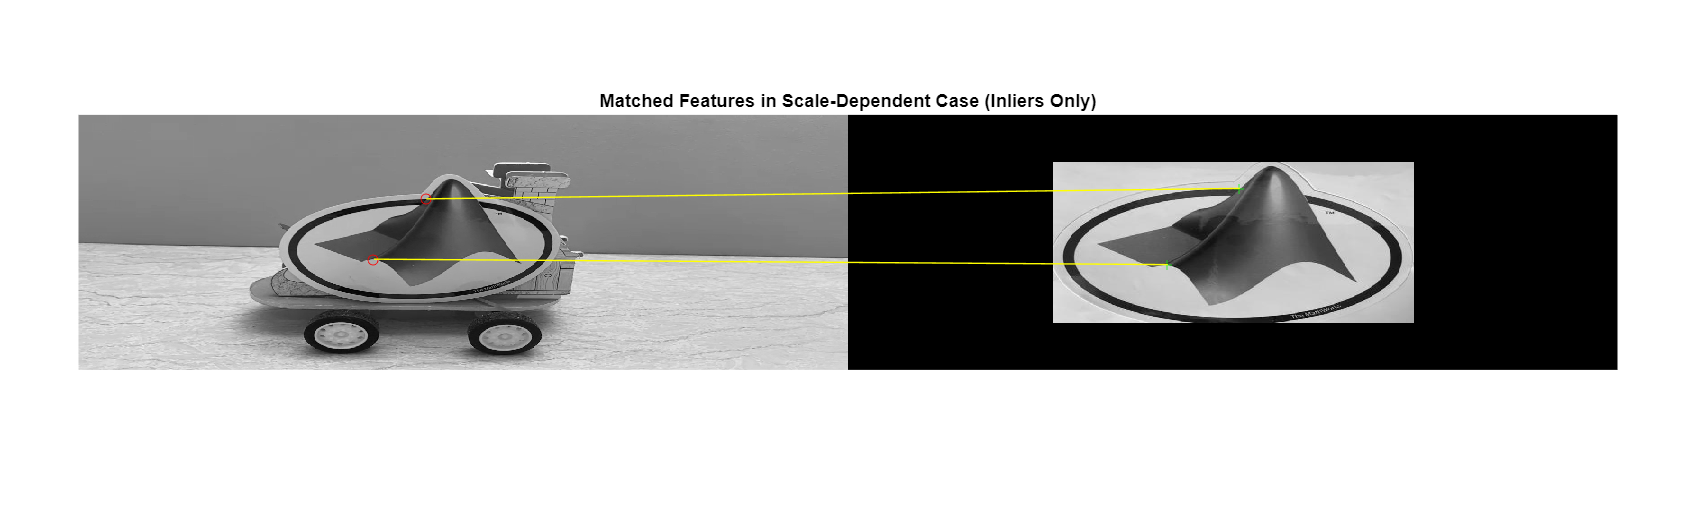

if statusD == 0
    frameInliersD = matchedFramePtsD(inlierIdxD, :);
    refInliersD = matchedRefPtsD(inlierIdxD, :);

    figure;
    showMatchedFeatures(frameImgGray, refImgGray, frameInliersD, ...
        refInliersD, 'montage');
    title('Matched Features in Scale-Dependent Case (Inliers Only)');
end

### Estimate Geometric Transformation in Scale-Independent Case

[tformI, inlierIdxI, statusI] = ...
    estimateGeometricTransform2D(matchedRefPtsI, matchedFramePtsI,'similarity'); % status = 0: No error; 1: not enough input points; 2: not enough inliers have been found


If there are enough inliers, display the matching point pairs.

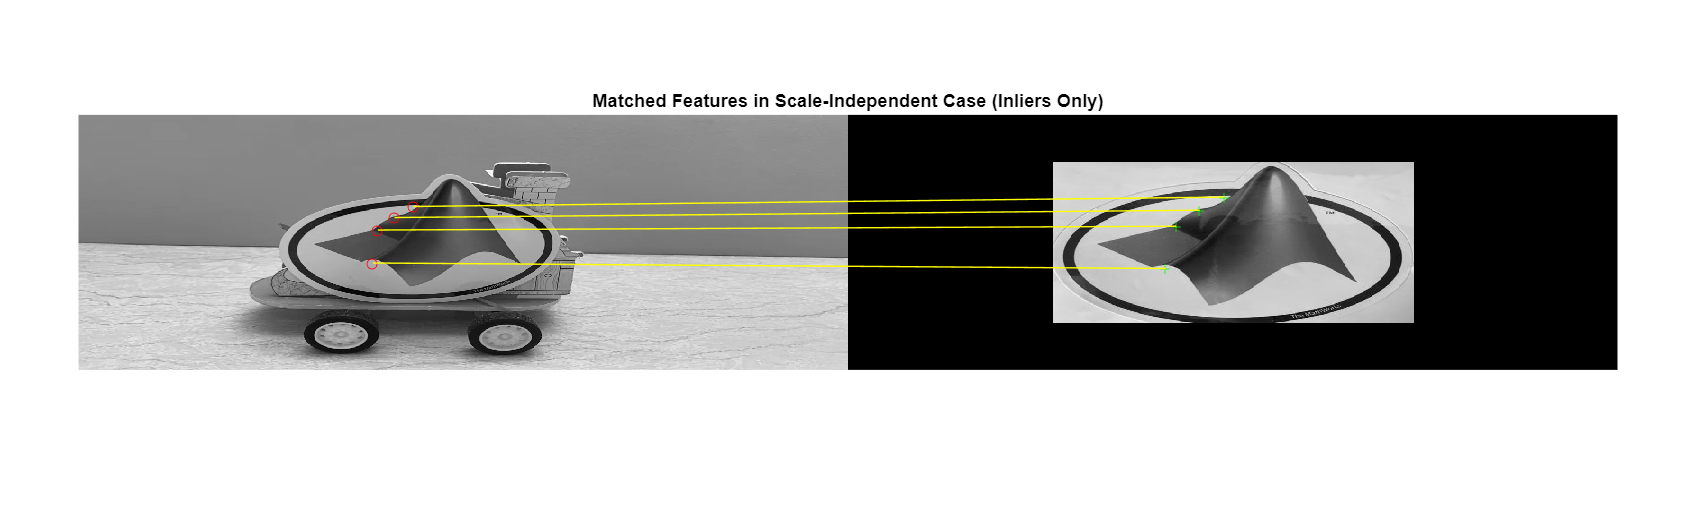

if statusI == 0
    frameInliersI = matchedFramePtsI(inlierIdxI, :);
    refInliersI = matchedRefPtsI(inlierIdxI, :);

    figure;
    showMatchedFeatures(frameImgGray, refImgGray, frameInliersI, ...
        refInliersI, 'montage');
    title('Matched Features in Scale-Independent Case (Inliers Only)');
end

## Future Tasks

- Tune the size of the reference image to see when the scale-dependent detectors and descriptors may work.